## Part 1

Fs = 2560, N = 512

### Q1)


$$\begin{array}{l}
\Delta f=\frac{\textrm{Fs}}{N}\\
\;\;\;\;\;\;\;=\frac{2560}{512}\\
\;\;\;\;\;\;\;=5\textrm{Hz}
\end{array}$$


### Q2)

Fn = 1/2Fs

Fn = 1280Hz

### Q3)

There are 512 analysis frequencies

### Q4)

First 2 are 5Hz and 10Hz

Middle 2 are 1275Hz and 1280Hz

Last 2 are 2555Hz and 2560Hz

### A)

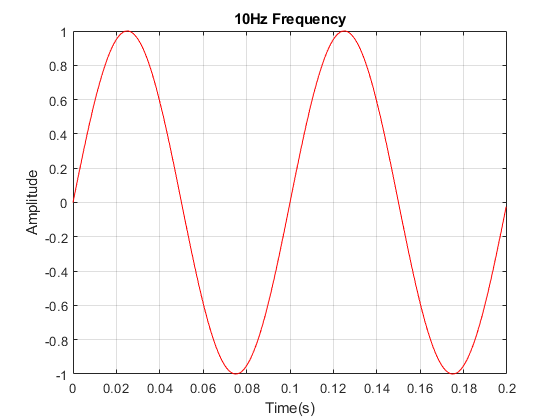

% inital values
N = 512; %Number of samples
f = 10; %Frequency
scaler = 1; %Scaling
amplitude = 1; %Amplitude
dc = 0; %DC offset
sampleRate = 2560; %Sample rate

[s1, s10] = Sinusoid(f, amplitude, sampleRate, N, scaler, dc);

figure(1);
plot(s1, s10, 'r'); 
title('10Hz Frequency');
xlabel 'Time(s)'; 
ylabel 'Amplitude'; 
grid on;

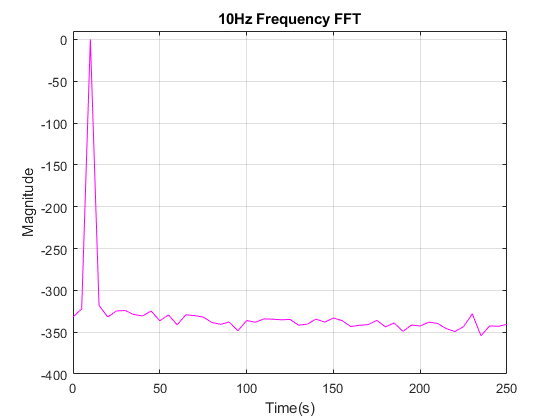



FFT = (fft(s10));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(2) %FFT
plot(fD, dB, 'm');             
grid on;
title('10Hz Frequency FFT');
xlabel 'Time(s)'; 
ylabel 'Magnitude'; 
xlim([0 250])
ylim([-400 10])

### B)

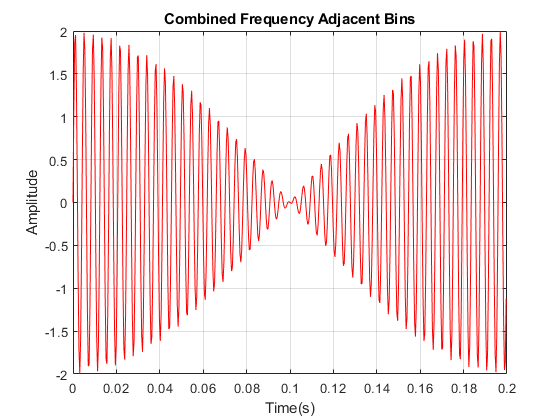

% inital values
N = 512; %Number of samples
f1 = 240; %Frequency
f2 = 245; %Frequency
scaler = 1; %Scaling
amplitude = 1; %Amplitude
dc = 0; %DC offset
sampleRate = 2560; %Sample rate

[s1, s240] = Sinusoid(f1, amplitude, sampleRate, N, scaler, dc);
[s2, s245] = Sinusoid(f2, amplitude, sampleRate, N, scaler, dc);

combined = LinCombo(s240, 1, s245, 1, 0);

FFT = (fft(combined));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(1); %discrete time signal
plot(s1, combined, 'r'); 
title('Combined Frequency Adjacent Bins');
xlabel 'Time(s)'; 
ylabel 'Amplitude'; 
grid on;

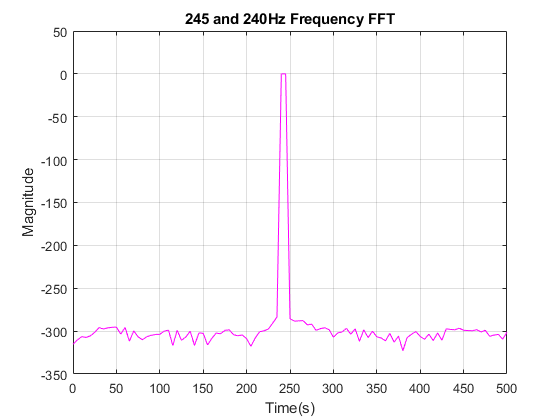


figure(2) %FFT
plot(fD, dB, 'm');              
grid on;
title('245 and 240Hz Frequency FFT');
xlabel 'Time(s)'; 
ylabel 'Magnitude'; 
xlim([0 500])

### C)

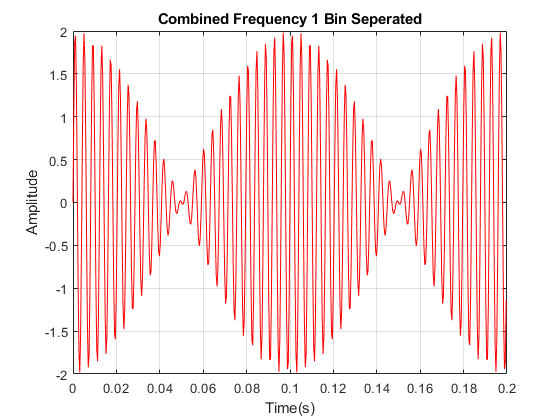

% inital values
N = 512; %Number of samples
f1 = 240; %Frequency
f2 = 250; %Frequency
scaler = 1; %Scaling
amplitude = 1; %Amplitude
dc = 0; %DC offset
sampleRate = 2560; %Sample rate

[s1, s240] = Sinusoid(f1, amplitude, sampleRate, N, scaler, dc);
[s2, s245] = Sinusoid(f2, amplitude, sampleRate, N, scaler, dc);

combined = LinCombo(s240, 1, s245, 1, 0);

FFT = (fft(combined));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(1); %discrete time signal
plot(s1, combined, 'r'); 
title('Combined Frequency 1 Bin Seperated');
xlabel 'Time(s)'; 
ylabel 'Amplitude'; 
grid on;

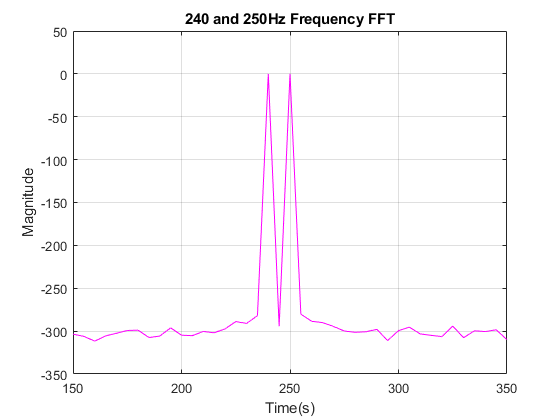


figure(2); %FFT
plot(fD, dB, 'm');             
grid on;
title('240 and 250Hz Frequency FFT');
xlabel 'Time(s)'; 
ylabel 'Magnitude'; 
xlim([150 350])

### D)

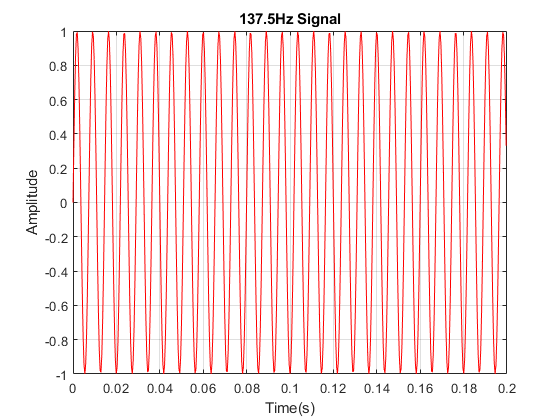

% inital values
N = 512; %Number of samples
f = 137.5; %Frequency
scaler = 1; %Scaling
amplitude = 1; %Amplitude
dc = 0; %DC offset
sampleRate = 2560; %Sample rate

[s1, s137] = Sinusoid(f, amplitude, sampleRate, N, scaler, dc);

FFT = (fft(s137));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(1); %discrete time signal
plot(s1, s137, 'r'); 
title('137.5Hz Signal');
xlabel 'Time(s)'; 
ylabel 'Amplitude'; 
grid on;

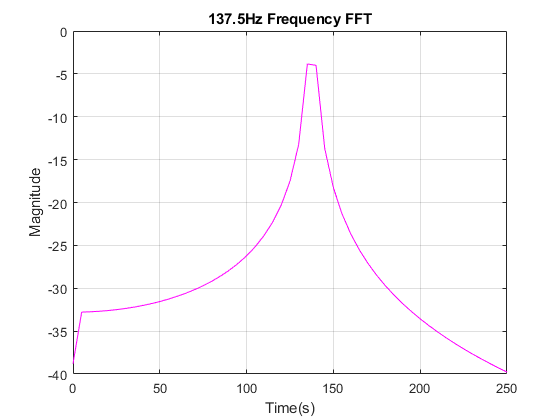


figure(2) %FFT
plot(fD, dB, 'm');              
grid on;
title('137.5Hz Frequency FFT');
xlabel 'Time(s)'; 
ylabel 'Magnitude'; 
xlim([0 250])

### E)

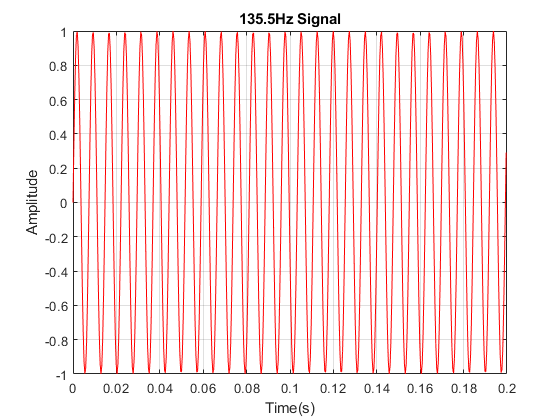

% inital values
N = 512; %Number of samples
f = 135.5; %Frequency
scaler = 1; %Scaling
amplitude = 1; %Amplitude
dc = 0; %DC offset
sampleRate = 2560; %Sample rate

[s1, s135] = Sinusoid(f, amplitude, sampleRate, N, scaler, dc);

FFT = (fft(s135));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(1); %discrete time signal
plot(s1, s135, 'r'); 
title('135.5Hz Signal');
xlabel 'Time(s)'; 
ylabel 'Amplitude'; 
grid on;

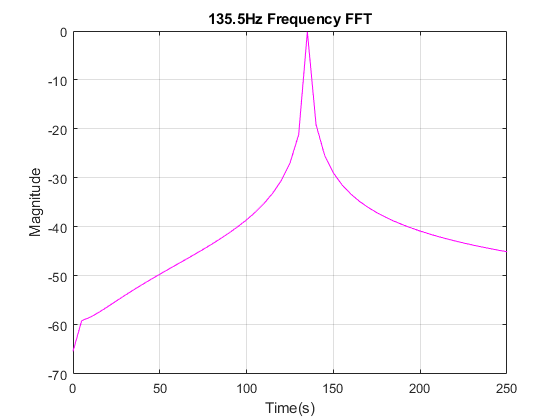


figure(2) %FFT
plot(fD, dB, 'm');              
grid on;
title('135.5Hz Frequency FFT');
xlabel 'Time(s)'; 
ylabel 'Magnitude'; 
xlim([0 250]);

## Part 2

### 1) 

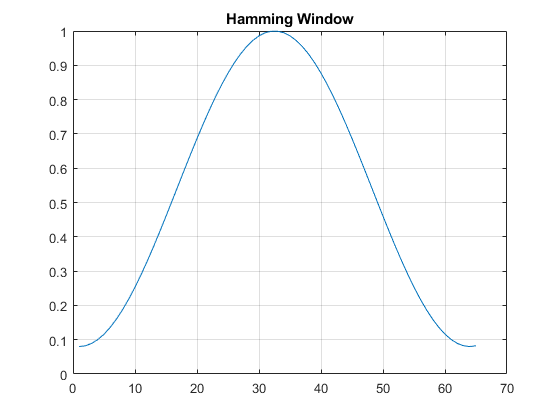

figure(1);
plot(Hamming(64));
title('Hamming Window');
grid on;

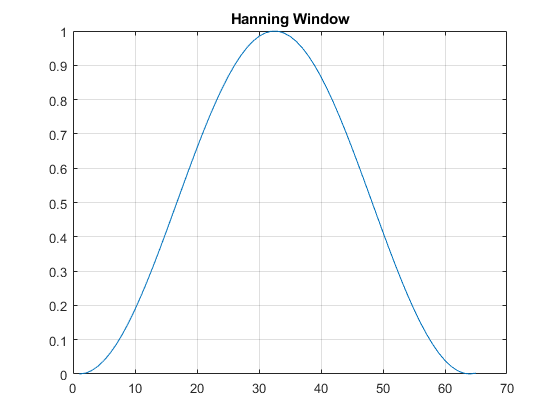


figure(2);
plot(Hanning(64));
title('Hanning Window');
grid on;

### 2)

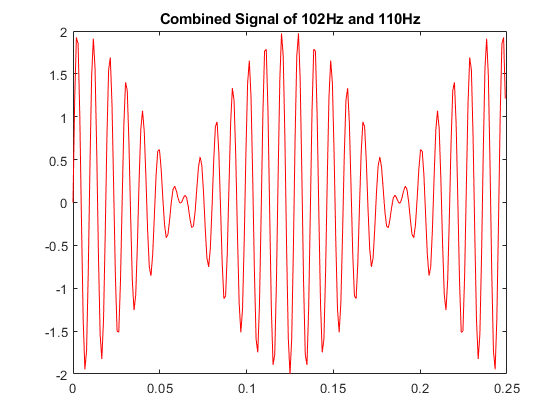

% inital values
N = 256; %Number of samples
f1 = 102; %Frequency
f2 = 110; %Frequency
scaler = 1; %Scaling
amplitude = 1; %Amplitude
dc = 0; %DC offset
sampleRate = 1024; %Sample rate

[s1, s102] = Sinusoid(f1, amplitude, sampleRate, N, scaler, dc);
[s2, s110] = Sinusoid(f2, amplitude, sampleRate, N, scaler, dc);

combined = LinCombo(s102,1,s110,1,0);

figure(1);
plot(s2, combined, 'r');
title('Combined Signal of 102Hz and 110Hz');

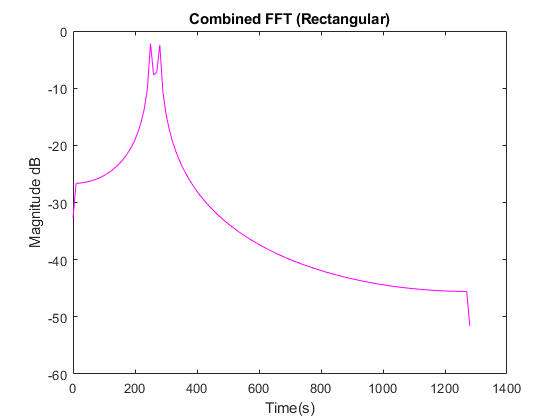



FFT = (fft(combined));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(2);
plot(fD, dB, 'm');
title('Combined FFT (Rectangular)');
xlabel 'Time(s)'; 
ylabel 'Magnitude dB'; 

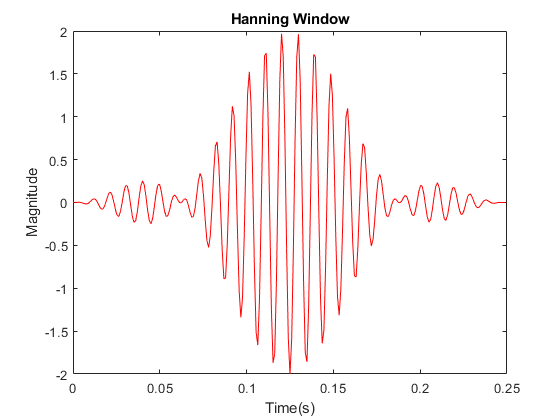

Windowed = SigMult(combined, Hanning(255));

figure(1);
plot(s1 , Windowed, 'r');
title('Hanning Window');
xlabel 'Time(s)'; 
ylabel 'Magnitude'; 

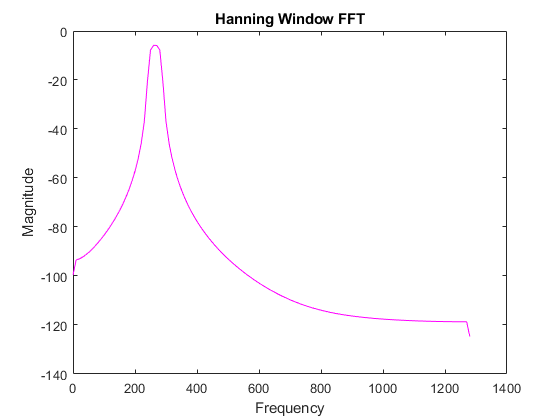



FFT = (fft(Windowed));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(2);
plot(fD, dB, 'm');
title('Hanning Window FFT');
xlabel 'Frequency'; 
ylabel 'Magnitude'; 

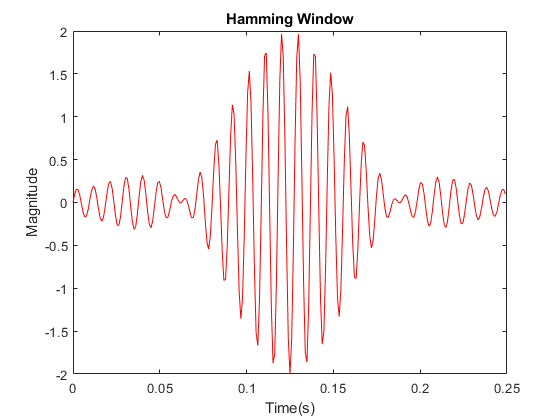

Windowed = SigMult(combined, Hamming(255));

figure(1);
plot(s1 , Windowed, 'r');
title('Hamming Window');
xlabel 'Time(s)'; 
ylabel 'Magnitude'; 

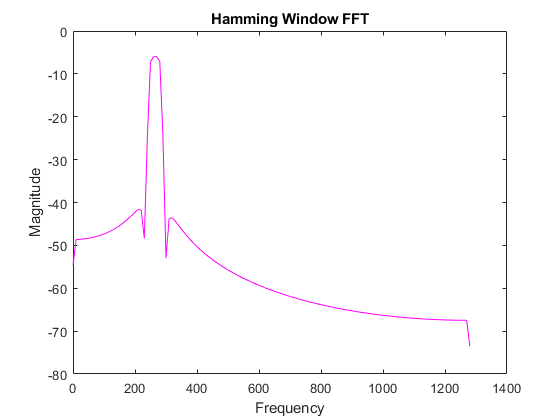



FFT = (fft(Windowed));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(2);
plot(fD, dB, 'm');
title('Hamming Window FFT');
xlabel 'Frequency'; 
ylabel 'Magnitude'; 

### 3)

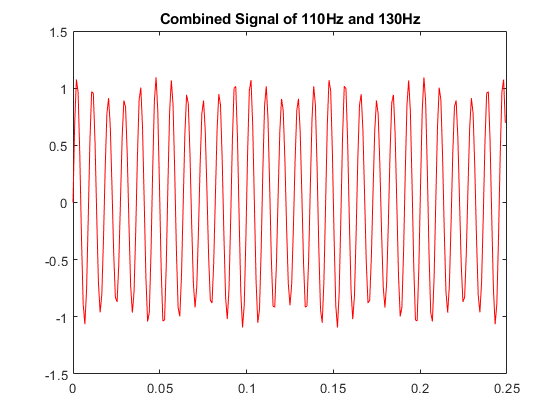

% inital values
N = 256; %Number of samples
f1 = 110; %Frequency
f2 = 130; %Frequency
scaler = 1; %Scaling
amplitude = 1; %Amplitude
dc = 0; %DC offset
sampleRate = 1024; %Sample rate

[s1, s110] = Sinusoid(f1, amplitude, sampleRate, N, scaler, dc);
[s2, s130] = Sinusoid(f2, 0.1, sampleRate, N, scaler, dc);

combined = LinCombo(s110,1,s130,1,0);

figure(1);
plot(s2, combined, 'r');
title('Combined Signal of 110Hz and 130Hz');

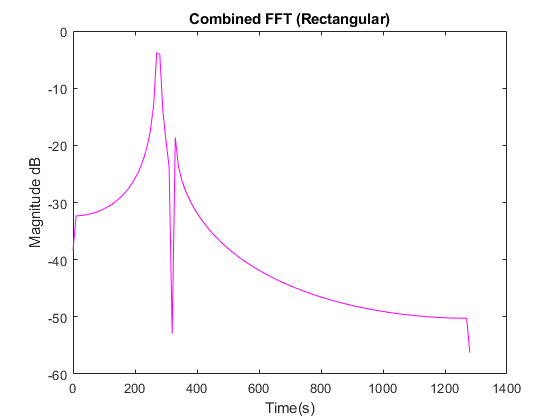



FFT = (fft(combined));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(2);
plot(fD, dB, 'm');
title('Combined FFT (Rectangular)');
xlabel 'Time(s)'; 
ylabel 'Magnitude dB'; 

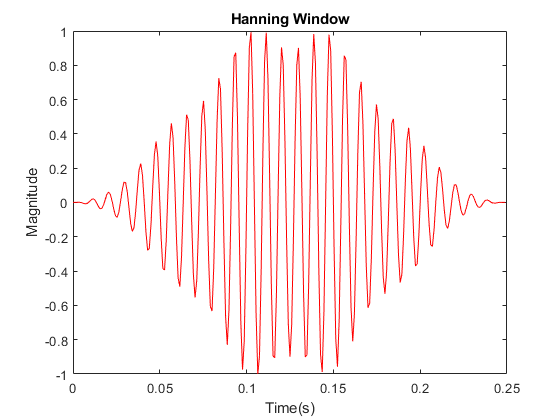

Windowed = SigMult(combined, Hanning(255));

figure(1);
plot(s1 , Windowed, 'r');
title('Hanning Window');
xlabel 'Time(s)'; 
ylabel 'Magnitude'; 

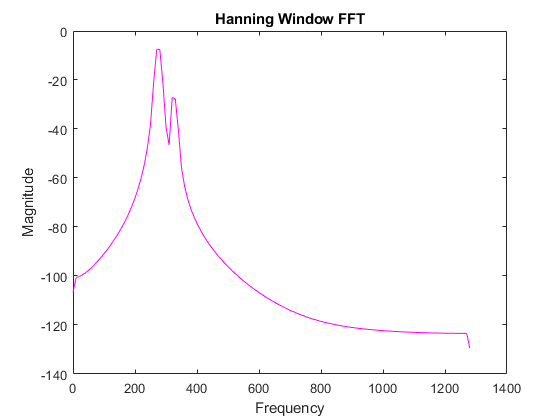



FFT = (fft(Windowed));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(2);
plot(fD, dB, 'm');
title('Hanning Window FFT');
xlabel 'Frequency'; 
ylabel 'Magnitude'; 

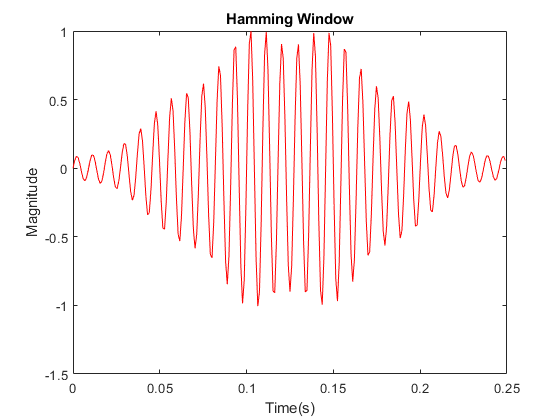

Windowed = SigMult(combined, Hamming(255));

figure(1);
plot(s1 , Windowed, 'r');
title('Hamming Window');
xlabel 'Time(s)'; 
ylabel 'Magnitude'; 

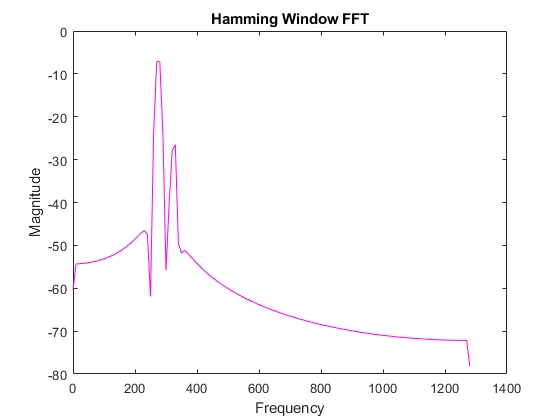



FFT = (fft(Windowed));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = 2560*(0:(N/2))/N;

figure(2);
plot(fD, dB, 'm');
title('Hamming Window FFT');
xlabel 'Frequency'; 
ylabel 'Magnitude'; 

### Q5

The Hanning window worked better.

### Q6

The Hamming window seems to have worked better for the second ase whereas the Hanning was better for the first case. So it would appear it depends on the signals being used. 

### Q8

102, 110 ,130 are all not in a bin since the bins are every 4Hz, but on the DFT they are shown in bnis:

102 - 250Hz bin

110 - 260Hz bin

130 - 270Hz bin

### Q9

No they are not. 

### Q10

no they could not be.